# enre 447 final prep

## 2017 sample final

### p01

ti = sort([7.74; 15.05; 20.46; 24.02; 28.66; 41.40; 47.30])

ti =     7.7400
   15.0500
   20.4600
   24.0200
   28.6600
   41.4000
   47.3000


n = 11

n = 11

r = numel(ti)

r = 7

T = 100

T = 100

TTT = sum(ti)+(n-r)*T

TTT = 584.6300


fhat = zeros(size(ti));
Rhat = zeros(size(ti));
hhat = zeros(size(ti));
for i=1:6
    fhat(i) = 1/((n+0.25)*(ti(i+1)-ti(i)));
    Rhat(i) = (n-i+0.625)/(n+0.25);
    hhat(i) = 1/((n-i+0.625)*(ti(i+1)-ti(i)));
end

fhat, Rhat, hhat

fhat =     0.0122
    0.0164
    0.0250
    0.0192
    0.0070
    0.0151
         0


Rhat =     0.9444
    0.8556
    0.7667
    0.6778
    0.5889
    0.5000
         0


hhat =     0.0129
    0.0192
    0.0326
    0.0283
    0.0118
    0.0301
         0


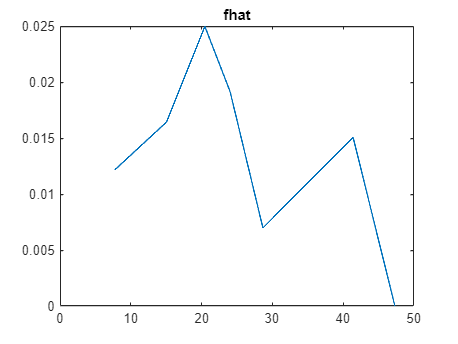


plot(ti, fhat); title("fhat")

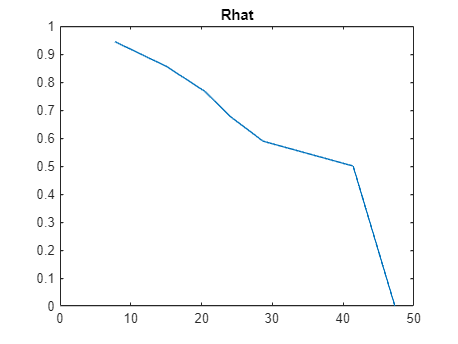

plot(ti, Rhat); title("Rhat")

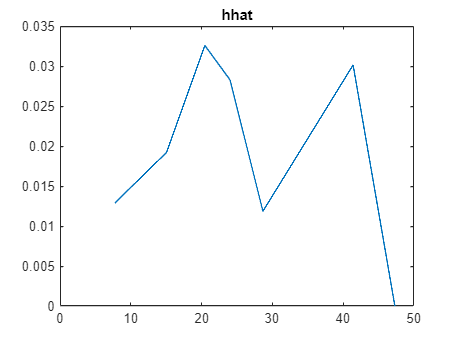

plot(ti, hhat); title("hhat")


logt = log(ti)

logt =     2.0464
    2.7114
    3.0185
    3.1789
    3.3555
    3.7233
    3.8565


loglogRinv = log(log(1./Rhat))

loglogRinv =    -2.8619
   -1.8579
   -1.3254
   -0.9443
   -0.6358
   -0.3665
       Inf


loglogRinv(r) = 0

loglogRinv =    -2.8619
   -1.8579
   -1.3254
   -0.9443
   -0.6358
   -0.3665
         0



linfit = polyfit(logt, loglogRinv, 1)

linfit =     1.5676   -6.0439


xfit = 2:4

xfit =      2     3     4


yfit = polyval(linfit, xfit)

yfit =    -2.9087   -1.3411    0.2265



slope = linfit(1)

slope = 1.5676

yint = linfit(2)

yint = -6.0439

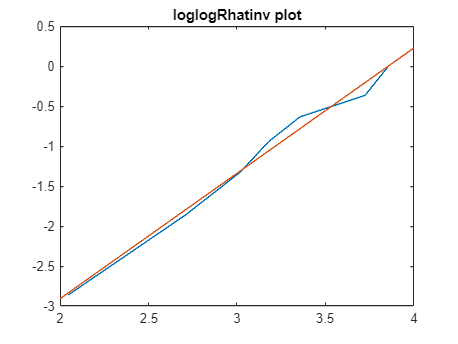


plot(logt, loglogRinv, xfit, yfit);
title("loglogRhatinv plot");


beta = slope

beta = 1.5676

alpha = exp(-yint/beta)

alpha = 47.2525


lambda = 1/alpha

lambda = 0.0212

lambdahat = r/TTT

lambdahat = 0.0120

gamma = 0.95

gamma = 0.9500


chi2inv(gamma, 2*r+2)/(2*TTT)

ans = 0.0225

## 2019 sample midterm

syms x t
f = 0.000192*t^2

$$f = \frac{3\,t^{2}}{15625}$$

R = int(f, [0 21]) + int(f, [x 25])

$$R = \frac{24886}{15625}-\frac{x^{3}}{15625}$$

MTTF = double   (int(f*t, [0 25]))

MTTF = 18.7500